clearvars;
close all;

Lx = 1; % Longueur x
Ly = 1; % Longueur y
r = 0.1; % Rayon des charges
kc = 100; % Conductivité charges
ki = 1; % Conductivité isolant
Nx = 256; % Nb de points x
Ny = 256; % Nb de points y

fstart = 0.04; % f de départ
fend = 1.0; % f final
df = 0.02; % pas
Nb = 50; % Nb de simulations pour une valeur de fs
Ncores = maxNumCompThreads() % Nb threads disponibles

Ncores = 4


f_list = fstart:df:fend;
num_steps = length(f_list);

lambda = zeros(num_steps, Nb);
F = zeros(num_steps, Nb);

lambdaMin = zeros(num_steps, 1);
Fmin = zeros(num_steps, 1);
lambdaMax = zeros(num_steps, 1);
Fmax = zeros(num_steps, 1);

if isempty(gcp('nocreate'))
    parpool('local', Ncores);
end

% Allows to measure progress
D = parallel.pool.DataQueue;
afterEach(D, @(fs_done) updateProgress(fs_done, num_steps));

tic
parfor i = 1:num_steps
    fs = f_list(i);

    [Fmin(i), lambdaMin(i), Fmax(i), lambdaMax(i)] = ResoMinMax2D(Lx, Ly, r, fs, kc, ki, Nx, Ny);

    for j=1:Nb
        [F(i, j), lambda(i, j)] = Reso1Cas2D(Lx, Ly, r, fs, kc, ki, Nx, Ny);
    end
    send(D, fs);
end
lambdaEq = mean(lambda, 2);
Favg = mean(F, 2);

toc

Elapsed time is 1436.115083 seconds.


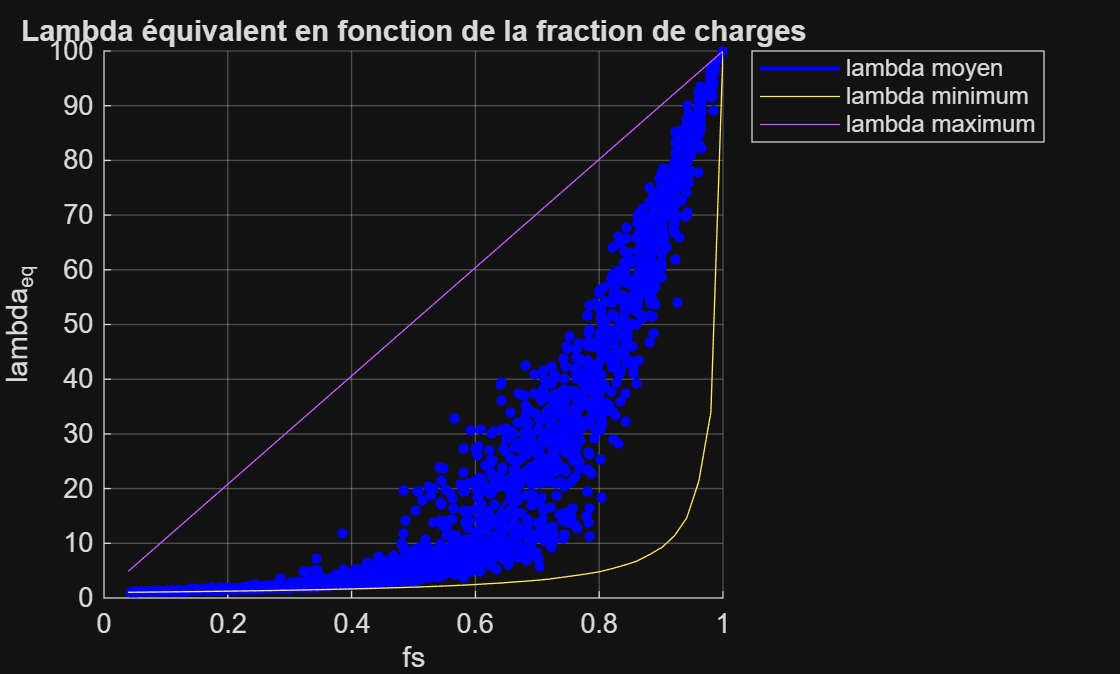


scatter(F(:), lambda(:), 15, 'b', 'filled', 'HandleVisibility', 'off');
hold on
plot(Favg, lambdaEq, 'b', 'LineWidth', 1.5, 'DisplayName', "lambda moyen")
plot(Fmin, lambdaMin, 'DisplayName', "lambda minimum")
plot(Fmax, lambdaMax, 'DisplayName', "lambda maximum")
xlabel("fs")
ylabel("lambda_{eq}")
grid on
legend('Location', 'northeastoutside')
title("Lambda équivalent en fonction de la fraction de charges")


pctRunOnAll clearvars;


function updateProgress(fs_val, total_steps)
    persistent count
    if isempty(count)
        count = 0;
    end
    count = count + 1;
    fprintf("Progress: %d/%d (%.1f%%) - Finished fs = %.2f\n", ...
            count, total_steps, (count / total_steps) * 100, fs_val);
end